# Basic MATLAB Techniques for Quantum Mechanics

## Eigenvalue problems in matlab

use the `eigs` or `eig` functions to solve for the eigenvalues and eigenvectors of an `NxN` matrix.

% example: let sigma be
% sigma_y = [0,-1i;1i,0]; % whose eigenvalues we know to be +/- 1
% [V,D] = eigs(sigma_y,2,'smallestabs')
% sigma.' gives the nonconjugate transpose
% sigma' gives the hermitian transpose of sigma.

a.)

To Solve for the eigenvalues we can use the formula for doing so for a matrix:$\text{det}(M - \lambda I) = 0$  where 


$$M = \pmatrix{1 & -0.1 \cr -0.1 & 1}$$


and $\text{det}(M - \lambda I) = \big|\matrix{1 - \lambda & -0.1 \cr -0.1 & 1- \lambda}\big| = \lambda^2 - 2\lambda + 0.99 = 0$

such that $\lambda = 1.1,0.9$

For the eigenvectors, we make use of the fact that $Mv = \lambda v

$ can be written as $(M - \lambda I)v = 0$ and solve for $v$.

When $\lambda = 0.9$, $(M - \lambda I) = \pmatrix{0.1 & -0.1 \cr -0.1 & 0.1}$. If we then apply this to a vector $v = \pmatrix{v_1 \cr v_2}$we find a system of linear equations $\matrix{0.1v_1 - 0.1v_2=0 \cr -0.1v_1 + 0.1v_2=0}$ suggesting that $v_1 = v_2$. We then choose $v_1 = 1 \rightarrow v_2 = 1$such that 


$$v_{\lambda = 0.9} = \pmatrix{1\cr 1}$$


when $\lambda = 1.1
$, we find that $(M - \lambda I) = \pmatrix{-0.1 & -0.1\cr -0.1 & -0.1}$such that $\matrix{-0.1v_1 -0.1v_2 = 0\cr -0.1v_1 -0.1v_2 = 0}$ which results in $v_{\lambda=1.1} = \pmatrix{1\cr -1}$ 

b.)

%%%%% Example from lab packet
M = [1,-0.1;-0.1,1];
[V,D] = eigs(M,2,'smallestabs')

V =    -0.7071   -0.7071
   -0.7071    0.7071


D =     0.9000         0
         0    1.1000


Notice that the eigenvectors produced numerically are different than those found analytically. This is because there is some ambiguity when choosing the components of the eigenvectors. -1 could have well been chosen to represent $v_1$when $\lambda = 1.1$and the analytical solutions would have matched the numeric solutions. The differences may be thought of as global phase factors. 

Also, the `eigs` function gives a normalized eigenvector.

c.) For two vectors to be orthonormal, they need to be orthogonal and normalized. This condition is manifested in 


$$\bar{\upsilon}_j^\dagger\cdot\bar{\upsilon}_k = \delta_{jk}$$


This means that if I perform the dot product between eigenvectors, the result should be zero. I perform an inner product with the vector with itself, it should be equal to 1

orthonormal = V(:,1)'*V(:,2)

orthonormal = 0

orthonormal = V(:,1)'*V(:,1)

orthonormal = 1.0000

orthonormal = V(:,2)'*V(:,2)

orthonormal = 1.0000

orthonormal = V(:,2)'*V(:,1)

orthonormal = 0

orthonormal = V'*V

orthonormal =     1.0000         0
         0    1.0000


d.) Symbolically, the definition of the expansion coefficients is given as 


$$\bar{v} = \sum_{j=1}^N c_j\bar{v}_j\quad,\quad c_j = \bar{v}_j^\dagger\cdot\bar{v}$$


Since the `eigs` function out puts a matrix `V` containing the eigenvectors as its columns, we can find a column vector of the expansion coefficients `c` by taking the adjoint of `V` and matrix multiplying it by the superposed vector. 

If we assume that $v = \pmatrix{3.3 \cr 7.1}
$is a superposition of the eigenstates of the matrix $M
$, then we can find the expansion coefficients as follows:

v = [3.3;7.1]

v =     3.3000
    7.1000


c = V'*v

c =    -7.3539
    2.6870


the apostrophe attached to `V` is the conjugate transpose operation in matlab. `V'=`$V^\dagger$. To do a transpose without conjugation use `V.'` .

Vector $v$ can now be written as $v = -7.3539\pmatrix{-1/\sqrt{2} \cr -1/\sqrt{2}} + 2.687\pmatrix{-1/\sqrt{2} \cr 1/\sqrt{2}}$. Recall that there is some ambiguity in the sign of the output of this expansion given the ambiguity in selecting the eigenvectors.

## A. Two-dimensional example

w = 1;
k = 0.1;

We are modelling coupled oscillators in this problem. The equations representing these oscillators are : 


$$\matrix{\frac{d^2 x_1}{dt^2} = -\omega^2 x_1 + \kappa x_2 \cr \frac{d^2 x_2}{dt^2} = -\omega^2 x_2 + \kappa x_1}$$


In order to make these equations more compliant for matlab if, for instance, we want to use `ode23` or `ode45` etcetera to solve the equations. These ode solvers only solve first order ordinary equations. The modified equations use $R_{1,3} = x_{1,2}
$ and $R_{2,4} = \frac{dx_{1,2}}{dt}$ and 


$$\frac{d}{dt}\pmatrix{R_1 \cr R_2 \cr R_3 \cr R_4} = \frac{d\bar{R}}{dt} = \pmatrix{0 & 1 & 0 & 0 \cr -\omega^2 & 0 & \kappa & 0 \cr0 & 0&0&1\cr\kappa&0&-\omega^2&0}\pmatrix{R_1 \cr R_2 \cr R_3 \cr R_4} = A\bar{R}$$


% initial conditions of R and their connection to x1 and x2
R10 = 1;
R30 = 0;
R20 = 0;
R40 = R20;
x10 = R10;
x20 = R30;

t= linspace(0,62.7,1000); % time vector
A = [0,1,0,0; -w^2, 0, k, 0; 0,0,0,1; k,0,-w^2,0] % ode matrix

A =          0    1.0000         0         0
   -1.0000         0    0.1000         0
         0         0         0    1.0000
    0.1000         0   -1.0000         0


R0 = [x10; R20; x20; R40] % initial condition vector

R0 =      1
     0
     0
     0


R = zeros(length(R0),length(t)); % R vector initialization
for i=1:length(t)
    R(:,i) = expm(A*t(i))*R0;
end



a.)

We know that $R_{1,3} = x_{1,2}$ so if we extract the first and third rows of `R` and plot them against `t` we will be plotting $x_{1,2}$

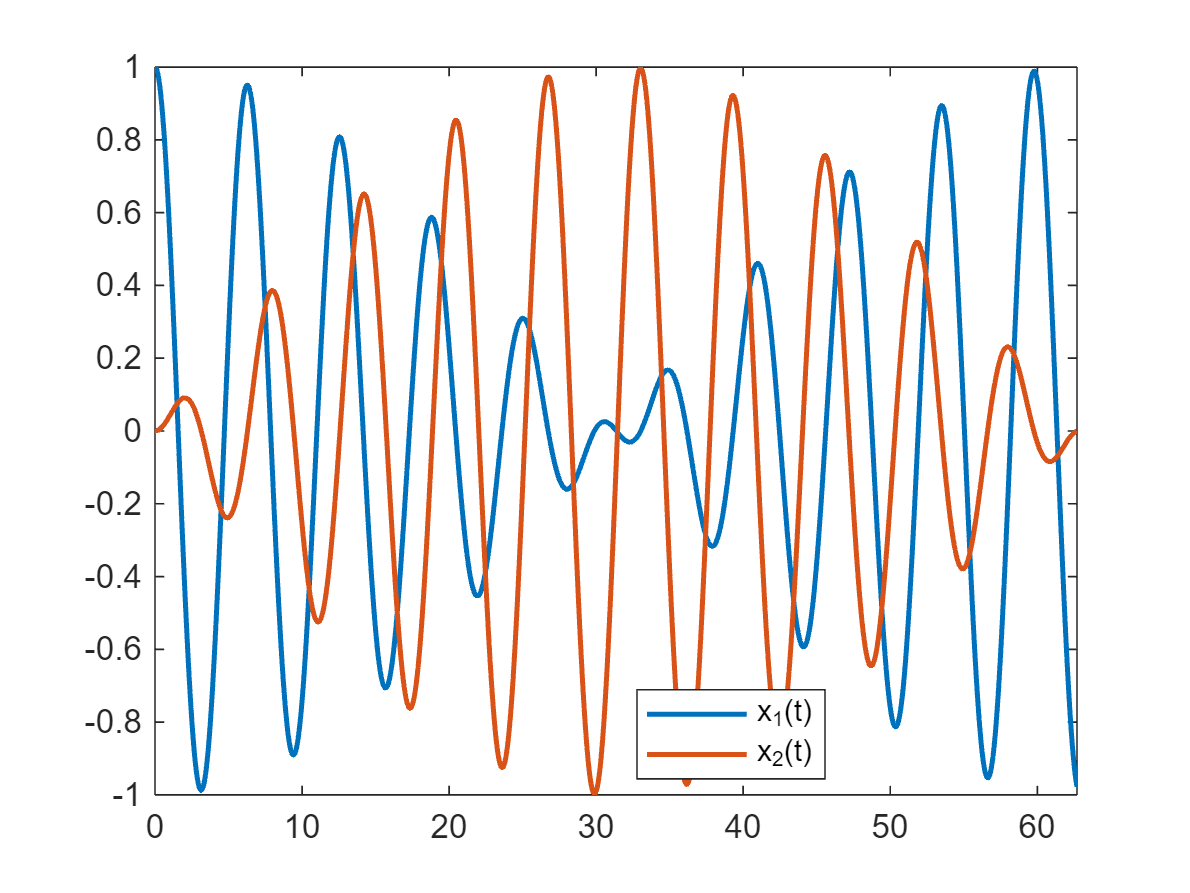

figure(1);
plot(t,R(1,:),'LineWidth',1.5);
hold on;
plot(t,R(3,:),'LineWidth',1.5);
legend('x_1(t)', 'x_2(t)',Location='best');
xlim([0,62.7]);
hold off;

b.) Time harmonic solutions of coupled oscillators


$$\bar{x}(t) = \pmatrix{x_1(t) \cr x_2(t)}=\cos(\Omega t)\bar{\upsilon}$$


if we commute the time harmonic solution's second derivative we find: 

$\matrix{\frac{d^2x_1}{dt^2} = -\Omega^2 \cos(\Omega t)\bar{v_1} \cr \frac{d^2x_2}{dt^2} = -\Omega^2 \cos(\Omega t)\bar{v_2} }$ if we write $\bar{v} = \pmatrix{\bar{v_1} \cr \bar{v_2}}$

Wewriting the above expression, and including it in the original set of coupled diff eqs


$$-\Omega^2\cos(\Omega t)\pmatrix{\bar{v_1} \cr \bar{v_2}} = \cos(\Omega t)\pmatrix{-\omega^2 & \kappa \cr \kappa & -\omega^2}\pmatrix{\bar{v_1} \cr \bar{v_2}}$$


After simplifying the above result we find that 


$$\pmatrix{-\omega^2 & \kappa \cr \kappa & -\omega^2}\pmatrix{\bar{v_1} \cr \bar{v_2}} = -\Omega^2\pmatrix{\bar{v_1} \cr \bar{v_2}}$$


Since we know $\omega$ and $\kappa$ we can find what $\Omega$ is.

B = [-w^2, k; k, -w^2];
[V,D] = eigs(B,2,'smallestabs')

V =     0.7071    0.7071
    0.7071   -0.7071


D =    -0.9000         0
         0   -1.1000


Omega = sqrt(-D)

Omega =     0.9487         0
         0    1.0488


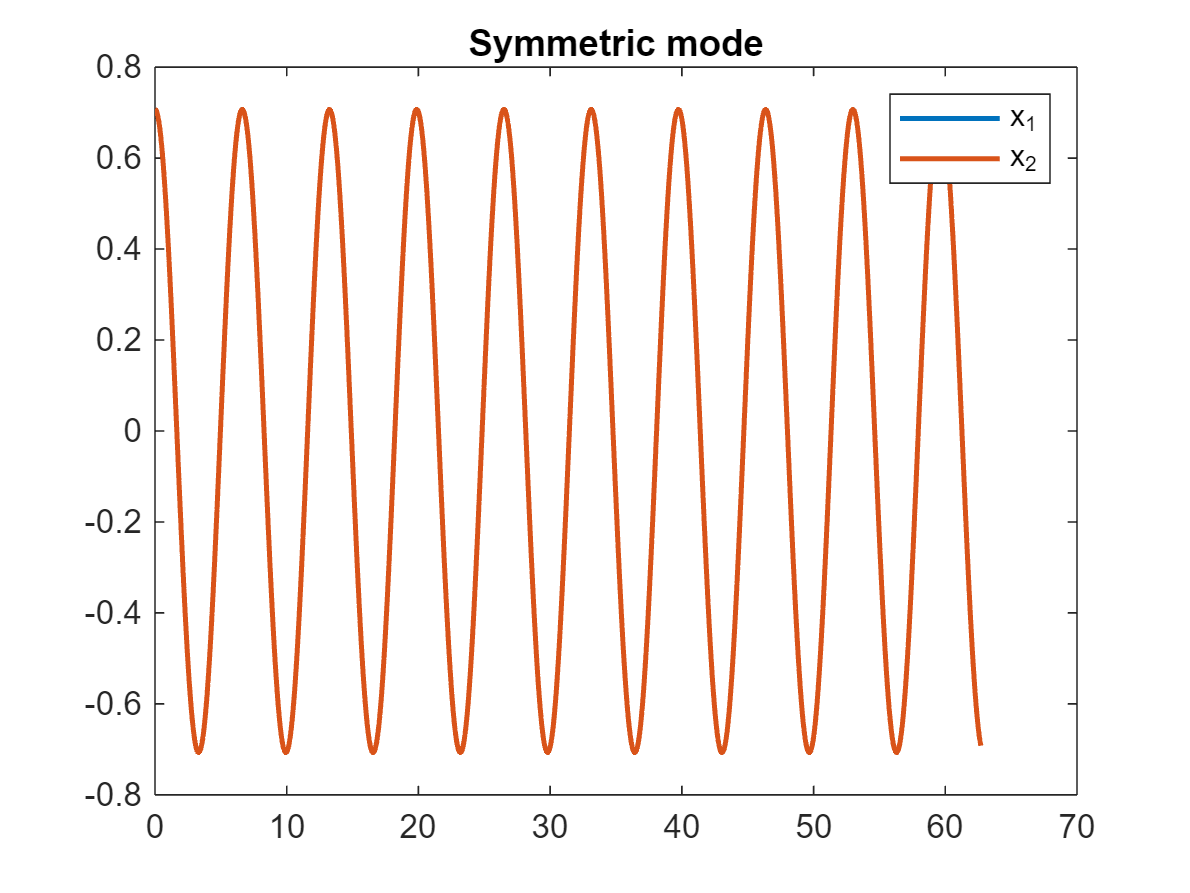

x1_eig1 = cos(Omega(1,1)*t)*V(1,1);
x2_eig1 = cos(Omega(1,1)*t)*V(2,1);
x1_eig2 = cos(Omega(2,2)*t)*V(1,2);
x2_eig2 = cos(Omega(2,2)*t)*V(2,2);
figure(2);
plot(t,x1_eig1,'LineWidth',1.5);
hold on;
plot(t,x2_eig1,'LineWidth',1.5);
title('Symmetric mode');
hold off;
legend('x_1','x_2');

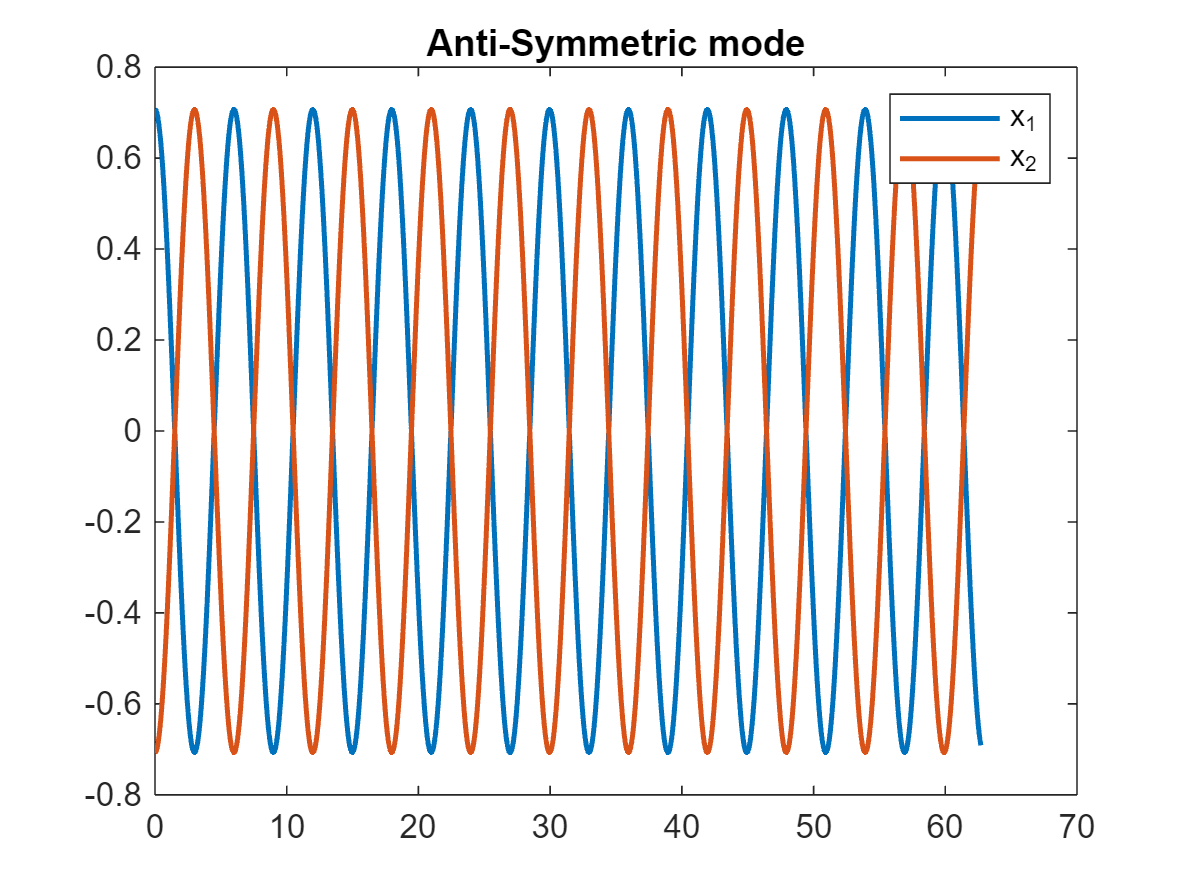

figure(3);
plot(t,x1_eig2,'LineWidth',1.5);
hold on;
plot(t,x2_eig2,'LineWidth',1.5);
title('Anti-Symmetric mode');
hold off;
legend('x_1','x_2');

c.) general initial condition 


$$\bar{x}(0) = \sum_{j=1}^2 c_j\bar{v_j}$$


To write the time varying expression is to include to cosine term: 


$$\bar{x}(t) = \sum_{j=1}^2 c_j\bar{v_j}\cos(\Omega_j t)$$


x0 = [1;0];
c = V'*x0

c =     0.7071
    0.7071


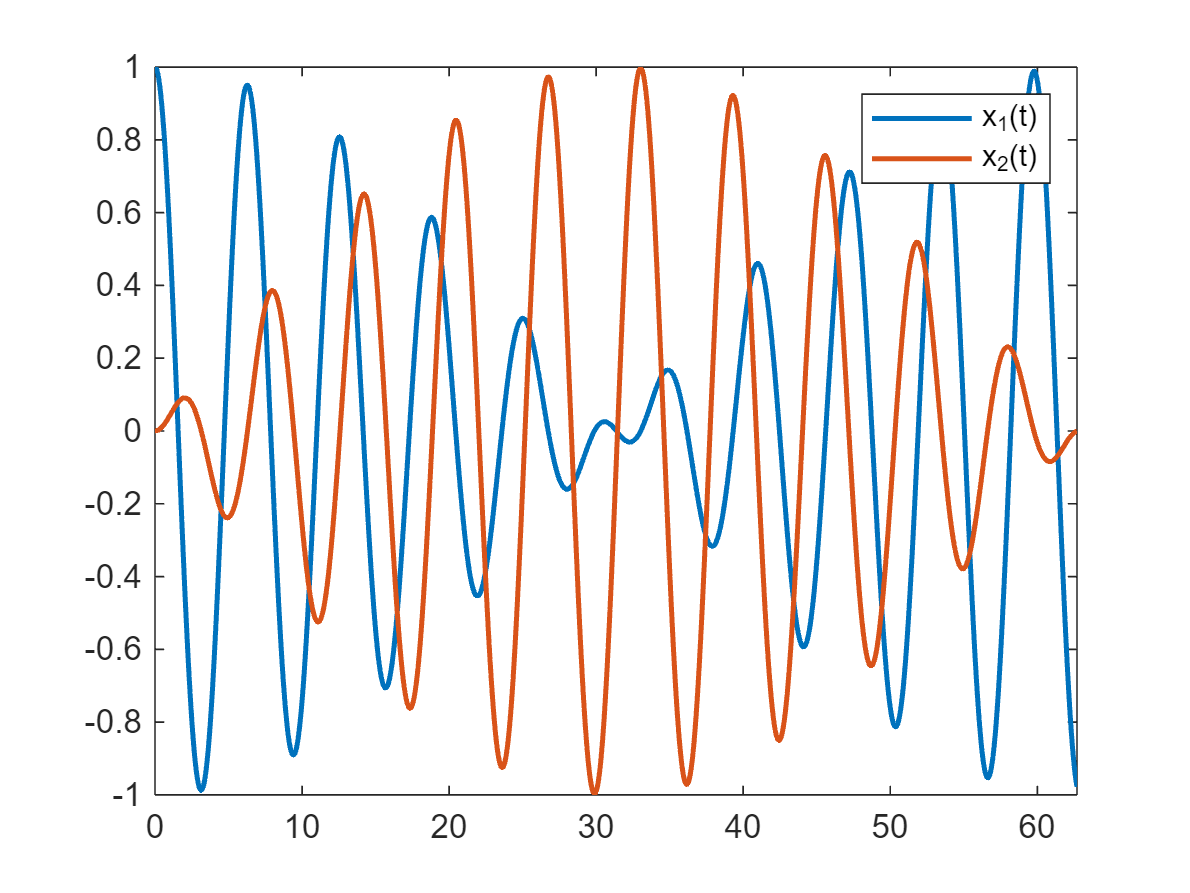


x1t_temp = c(1)*V(1,1)*cos(Omega(1,1)*t) + c(1)*V(1,2)*cos(Omega(2,2)*t);
x2t_temp = c(2)*V(2,1)*cos(Omega(1,1)*t) + c(2)*V(2,2)*cos(Omega(2,2)*t);
figure(4);
plot(t,x1t_temp,'LineWidth',1.5);
hold on; 
plot(t,x2t_temp,'LineWidth',1.5);
hold off;
legend('x_1(t)', 'x_2(t)');
xlim([0,62.7]);

d.) We find that the solution in c.) agrees with the solution in a.). This illustrates the fact that we can represent general states in a basis of eigenstates for that system.

## B. N-dimensional example

a.) for N coupled oscillator, specifically N weakly coupled oscillators, the differential equations that govern the system are: 

$\frac{d^2x_\mu}{dt^2} = -\omega_\mu^2x_\mu + \kappa x_{\mu+1} + \kappa x_{\mu-1}\quad,\quad \mu = 1,2,\dots,N$.

We also implement natural boundary conditions such that $x_0(t) = x_{N + 1}(t) = 0$ this means that the system of equations becomes the following: 


$$\matrix{\frac{d^2x_1}{dt^2} = -\omega_1^2x_1 + \kappa x_2 \cr \frac{d^2x_2}{dt^2} = -\omega_2^2x_2 + \kappa x_3 + \kappa x_1 \cr \frac{d^2x_3}{dt^2} = -\omega_3^2x_3 + \kappa x_4 + \kappa x_2\cr \vdots \cr  \frac{d^2x_\mu}{dt^2} = -\omega_\mu^2x_\mu + \kappa x_{\mu+1} + \kappa x_{\mu - 1}\cr\vdots\cr\frac{d^2x_{N-1}}{dt^2} = -\omega_{N-1}^2x_{N-1} + \kappa x_N + \kappa x_{N-2} \cr \frac{d^2x_N}{dt^2} = -\omega_N^2x_N + \kappa x_{N-1}}$$


Next, if we seek the time harmonic solution $\bar{x}(t) = \pmatrix{x_1 \cr x_2 \cr x_3\cr\vdots\cr x_\mu\cr\vdots\cr x_{N-1}\cr x_N} = \cos(\Omega t)\pmatrix{v_1\cr v_2\cr v_3\cr\vdots \cr v_\mu\cr\vdots\cr v_{N-1}\cr v_N }$ then we can write the set of differential equations as 


$$\matrix{\Omega^2 v_1 = \omega_1^2 v_1 + \kappa v_2 \cr \Omega^2 v_2 = \omega_2^2 v_2 + \kappa v_3 + \kappa v_1 \cr \Omega^2 v_3 = \omega_3^2 v_3 + \kappa v_2 + \kappa v_4 \cr\vdots\cr \Omega^2 v_{N-1} = \omega_{N-1}^2 v_{N-1} + \kappa v_{N-2} + \kappa v_N \cr \Omega^2 v_N = \omega_N^2 v_N + \kappa v_{N-1}}$$


Where the eigenvalues  are $\Omega^2$ and the accompanying matrix is represented as $\pmatrix{\omega_1^2 & -\kappa & 0& 0& \dots & 0 \cr -\kappa & \omega_2^2 & -\kappa & 0 &\dots& 0 \cr 0 & -\kappa & \omega_3^2 & -\kappa &\dots& 0\cr \vdots &\vdots & \vdots & \vdots&\vdots&\vdots \cr 0&\dots&0&0&-\kappa_\mu&\omega_\mu^2 }$

which is succintly represented using kronecker deltas as 


$$M_{\mu,\nu} = \omega_{\mu,\nu}^2\delta_{\mu,\nu} - \kappa[\delta_{\mu,\nu+1} + \delta_{\mu,\nu-1}]$$


b.) $N=41$, $\omega_\mu = 1$, $\kappa = 0.2$ 

M = zeros(41,41); % initialize oscillator matrix
w = 1; % give values for natural frequency
k = 0.2; % give value for coupling strength
% Assembling the Matrix M for specific values of w and k
for i = 1:length(M) % rows % \mu
    for j = 1:length(M) % columns %\nu
        if i == j
            M(i,j) = w;
        elseif i ==(j+ 1) || i == (j - 1)
            M(i,j) = -k;
        end
    end
end

% in order to get back the four smallest eigenvalues, I need to specify how
% man eigenvalues I want from the eigs function as well as in what
% direction to pull them from (highest, lowest)

[V,D] = eigs(M,41,'smallestabs')

V =     0.0163   -0.0325   -0.0486    0.0643    0.0797   -0.0947   -0.1091    0.1229    0.1361   -0.1484   -0.1600    0.1706    0.1803   -0.1890   -0.1966    0.2031    0.2085   -0.2127   -0.2158    0.2176    0.2182   -0.2176   -0.2158    0.2127    0.2085   -0.2031   -0.1966    0.1890    0.1803   -0.1706   -0.1600    0.1484    0.1361   -0.1229   -0.1091    0.0947    0.0797   -0.0643   -0.0486    0.0325    0.0163
    0.0325   -0.0643   -0.0947    0.1229    0.1484   -0.1706   -0.1890    0.2031    0.2127   -0.2176   -0.2176    0.2127    0.2031   -0.1890   -0.1706    0.1484    0.1229   -0.0947   -0.0643    0.0325    0.0000    0.0325    0.0643   -0.0947   -0.1229    0.1484    0.1706   -0.1890   -0.2031    0.2127    0.2176   -0.2176   -0.2127    0.2031    0.1890   -0.1706   -0.1484    0.1229    0.0947   -0.0643   -0.0325
    0.0486   -0.0947   -0.1361    0.1706    0.1966   -0.2127   -0.2182    0.2127    0.1966   -0.1706   -0.1361    0.0947    0.0486    0.0000    0.0486   -0.0947   -0.1361    

D =     0.6011         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.6045         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.6100         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

Omega= sqrt(D)

Omega =     0.7753         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.7775         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.7810         0         0         0         0         0         0         0         0         0         0         0         0         0         0

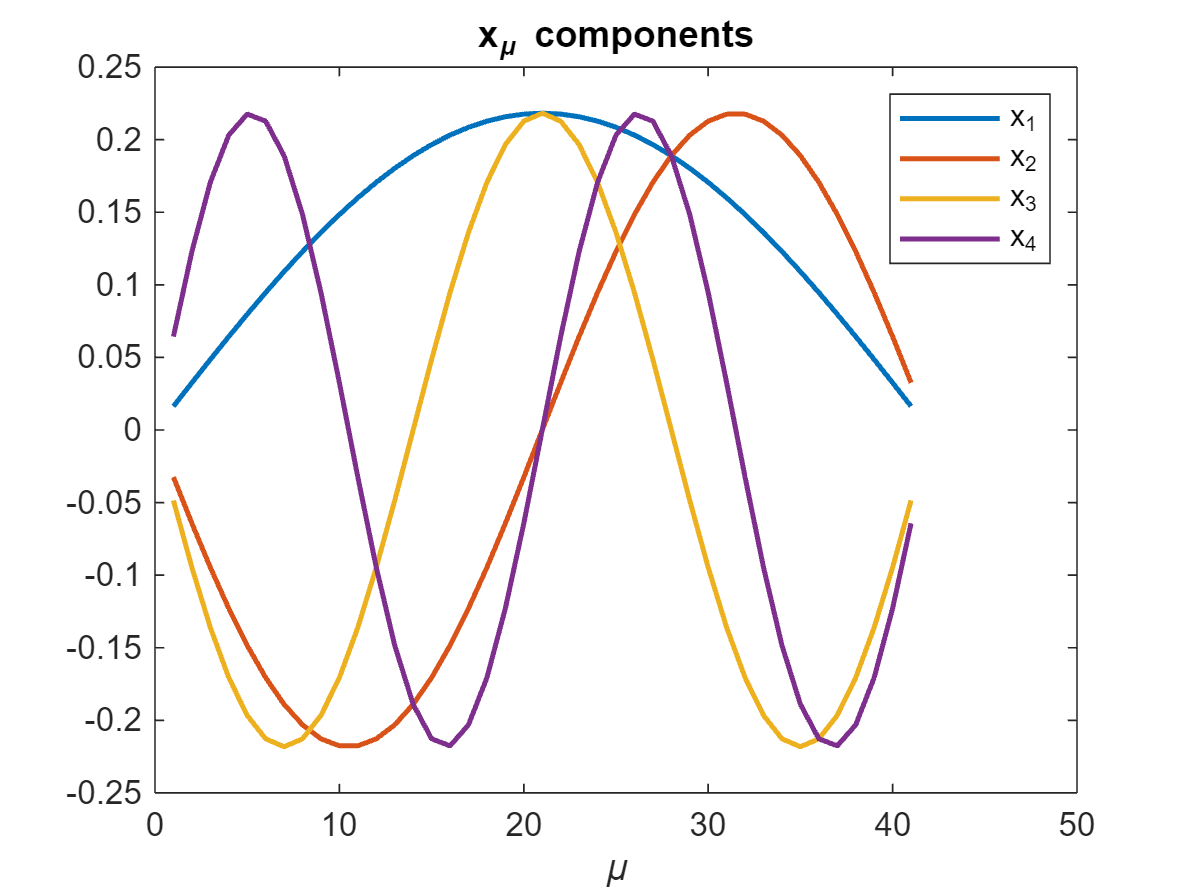

% these result in 41 eigenvectors with 41 components (mu)
% x_mu,nu == mu is the function x_mu and nu is the component of the
% eigenvector
% Grab the first 4 eigenvectors
x1 = V(:,1);
x2 = V(:,2);
x3 = V(:,3);
x4 = V(:,4);
% x1 components
figure(5);
plot(x1,'LineWidth',1.5);
hold on;
plot(x2,'LineWidth',1.5);
plot(x3,'LineWidth',1.5);
plot(x4,'LineWidth',1.5);
hold off;
title('x_\mu components');
xlabel('\mu');
legend('x_{1}','x_{2}','x_{3}','x_{4}');

The resulting functions are cosines with varying amplitudes depending on the component values of the eigenvectors that comprise each component. 

c.) The component solutions could be compared to rabi oscillation problems where the eigenvector values and eigenvalues determine the overall probability of a transition occuring to that state.

d.) 


$$\bar{x}(t) = \sum_{j=1}^2 c_j\bar{v_j}\cos(\Omega_j t)$$



$$\bar{x}(0) = \sum_{j=1}^N c_j\bar{\upsilon}_j$$


N = 41;
sigma = [10,100];
x01 = zeros(N,1); % hold initial conditions for sigma = 10
x02 = zeros(N,1); % hold initial conditions for sigma = 100
for mu = 1:N
    x01(mu) = exp(-(mu - 21)^2/sigma(1));
    x02(mu) = exp(-(mu - 21)^2/sigma(2));
end
t = linspace(0,1094,10000); % time vector
t1 = [0,547,1094]; % time stamps for later

c1 = V'*x01 % superposition coefficients for sigma = 10

c1 =     1.2061
   -0.0000
    1.0784
   -0.0000
    0.8622
   -0.0000
    0.6163
   -0.0000
    0.3939
    0.0000


c2 = V'*x02 % superposition coefficients for sigma = 100

c2 =     3.3646
   -0.0000
    1.0940
   -0.0000
    0.1228
   -0.0000
   -0.0017
   -0.0000
    0.0054
    0.0000


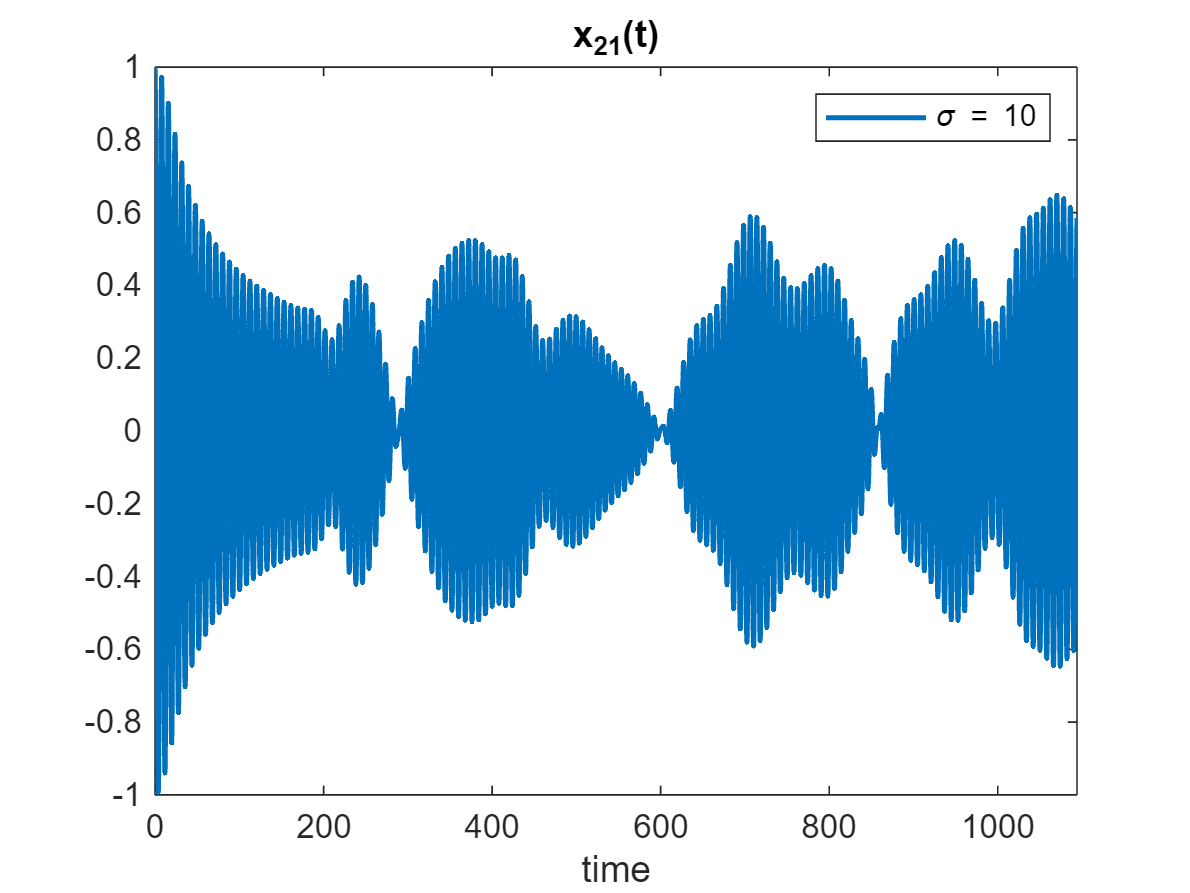


x1t_temp = zeros(N,length(t));      % temporary vectors to hold time dependence
x2t_temp = zeros(N,length(t));      % temporary vector to hold initial time dependent x_mu
x1t = zeros(N,length(t));
x2t = zeros(N,length(t));
% plotting x21
% time dependence will be included along the second dimension of xit
for j = 1:N         % loop over eigenvectors
    for t2 = 1:length(t)        % include time dependence
        % fill out the time evolution on the columns
        x1t_temp(:,t2) = c1(j)*V(:,j)*cos(Omega(j,j)*t(t2));
        x2t_temp(:,t2) = c2(j)*V(:,j)*cos(Omega(j,j)*t(t2)); 
    end
    if j == 1 
        x1t = x1t_temp;
        x2t = x2t_temp;
    else
        % sum up the weighted eigenvectors
        x1t = x1t + x1t_temp;
        x2t = x2t + x2t_temp;
    end
end
% plotting x21(t) %%%%%%%%%%%%%%%%%%%%%%%%
figure(6);
plot(t,x1t(21,:),'LineWidth',1.5); % x_mu for mu = 21
legend('\sigma = 10');
title('x_{21}(t)');
xlabel('time');
xlim([0, 1094]);

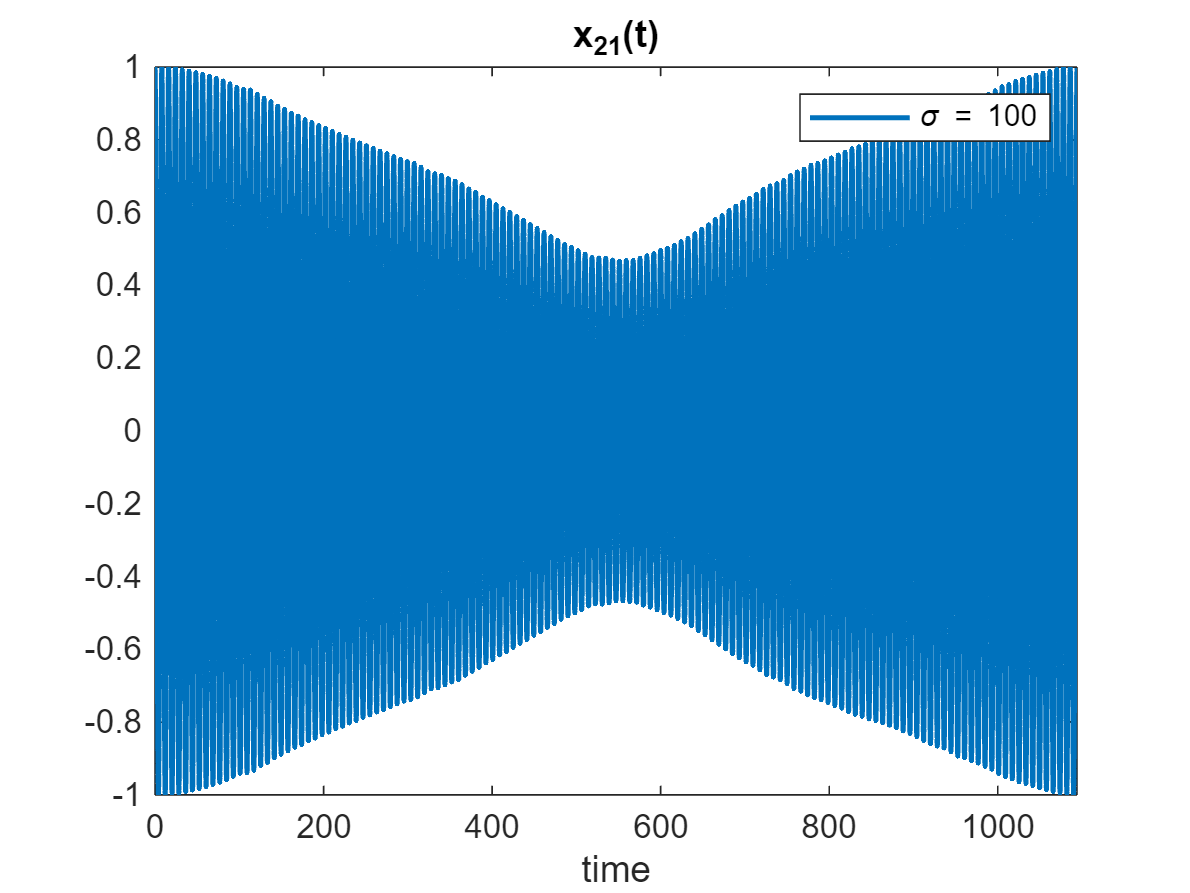

figure(7);
plot(t,x2t(21,:),'LineWidth',1.5);
legend('\sigma = 100');
title('x_{21}(t)');
xlabel('time');
xlim([0, 1094]);

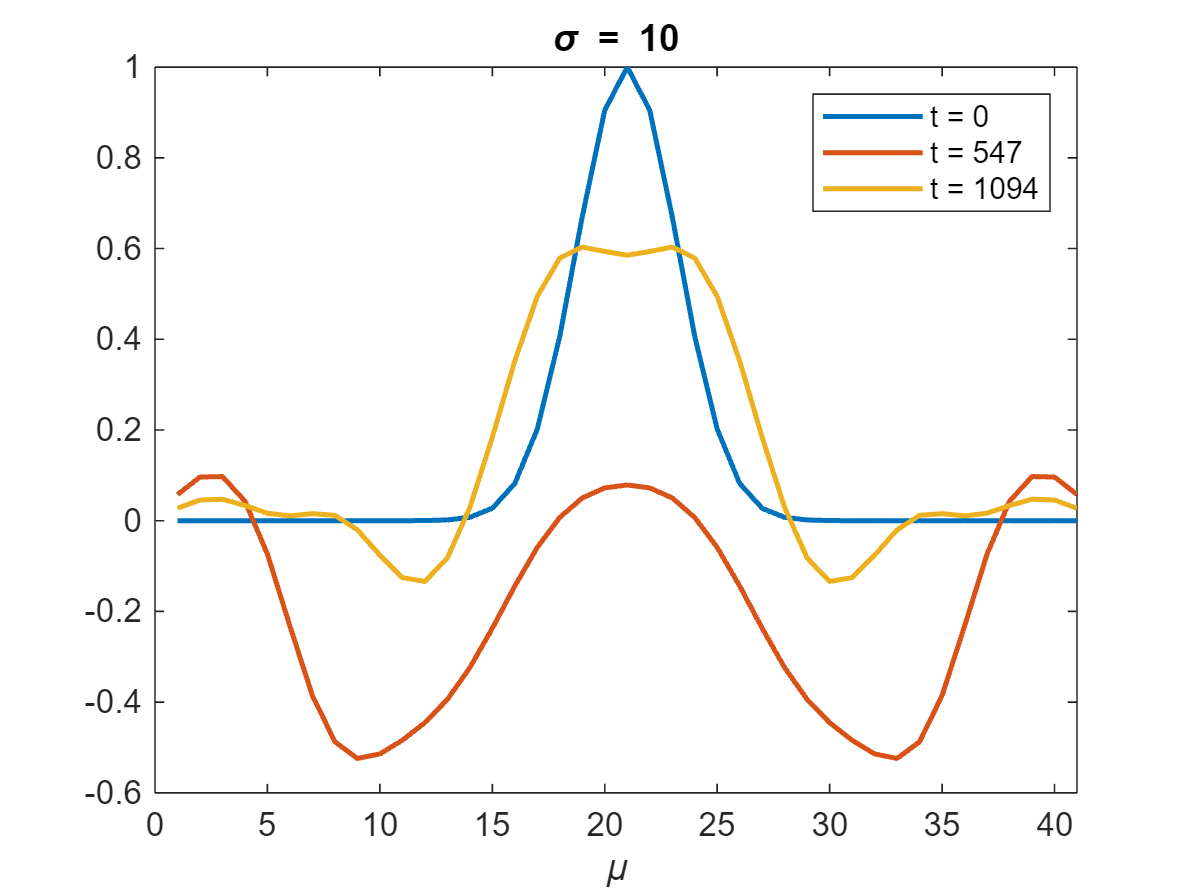

% setting up time stamps in for plotting x_mu
x1t_temp = zeros(N,length(t1));      % temporary vectors to hold time dependence
x2t_temp = zeros(N,length(t1));      % temporary vector to hold initial time dependent x_mu
x1t = zeros(N,length(t1));
x2t = zeros(N,length(t1));
for j = 1:N
    for t2 = 1:length(t1)
        x1t_temp(:,t2) = c1(j)*V(:,j)*cos(Omega(j,j)*t1(t2));
        x2t_temp(:,t2) = c2(j)*V(:,j)*cos(Omega(j,j)*t1(t2)); 
    end
    if j == 1 
        x1t = x1t_temp;
        x2t = x2t_temp;
    else
        x1t = x1t + x1t_temp;
        x2t = x2t + x2t_temp;
    end

end
% plotting x_mu %%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(8);
plot(x1t(:,1),'LineWidth',1.5);
hold on;
plot(x1t(:,2),'LineWidth',1.5);
plot(x1t(:,3),'LineWidth',1.5);
title('\sigma = 10');
legend('t = 0','t = 547','t = 1094');
xlabel('\mu');
xlim([0 41]);
hold off;

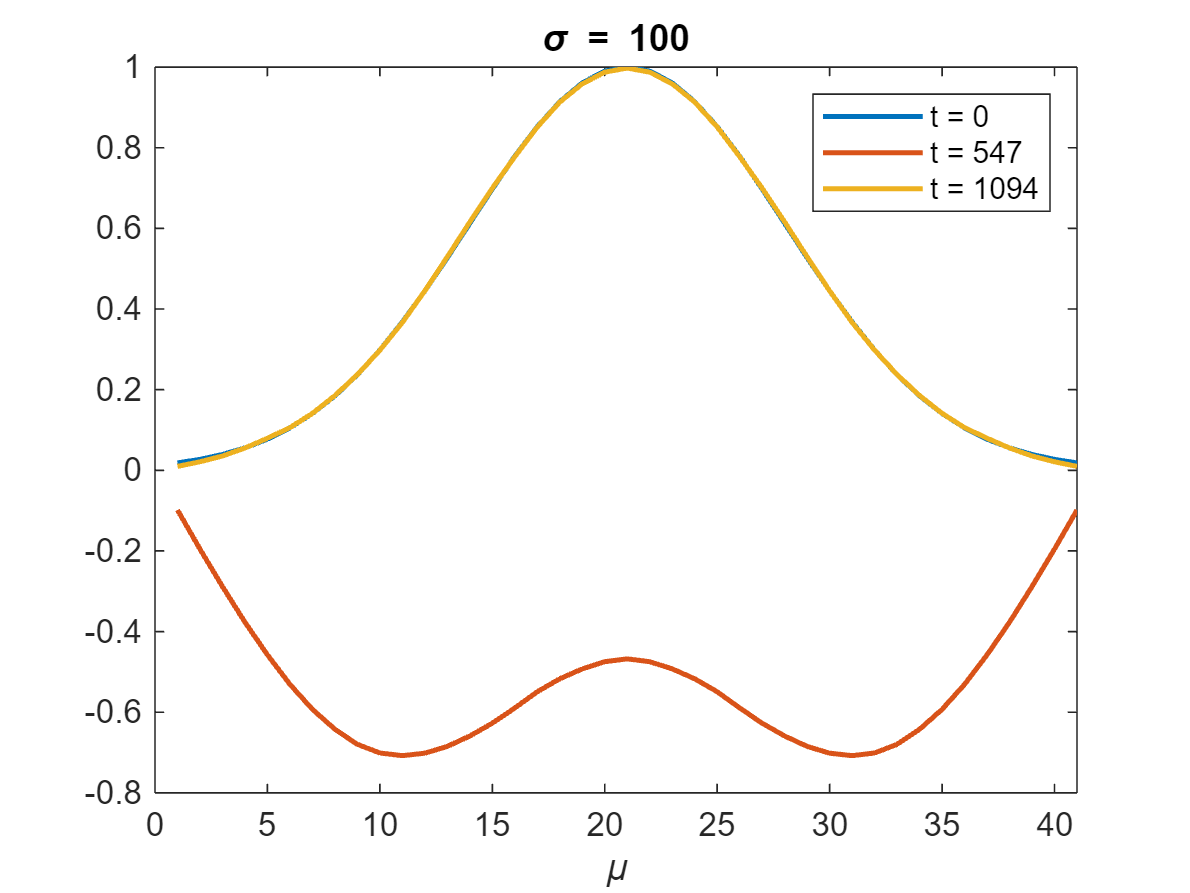


figure(9);
plot(x2t(:,1),'LineWidth',1.5);
hold on;
plot(x2t(:,2),'LineWidth',1.5);
plot(x2t(:,3),'LineWidth',1.5);
title('\sigma = 100')
legend('t = 0','t = 547','t = 1094');
xlim([0 41]);
xlabel('\mu');
hold off;

e.) 

The rationale has something to do with the fact that $c_j$ for $\sigma = 10$ includes more modes in its mode spectrum where as $c_j$ for $\sigma = 100$ does not include many modes.

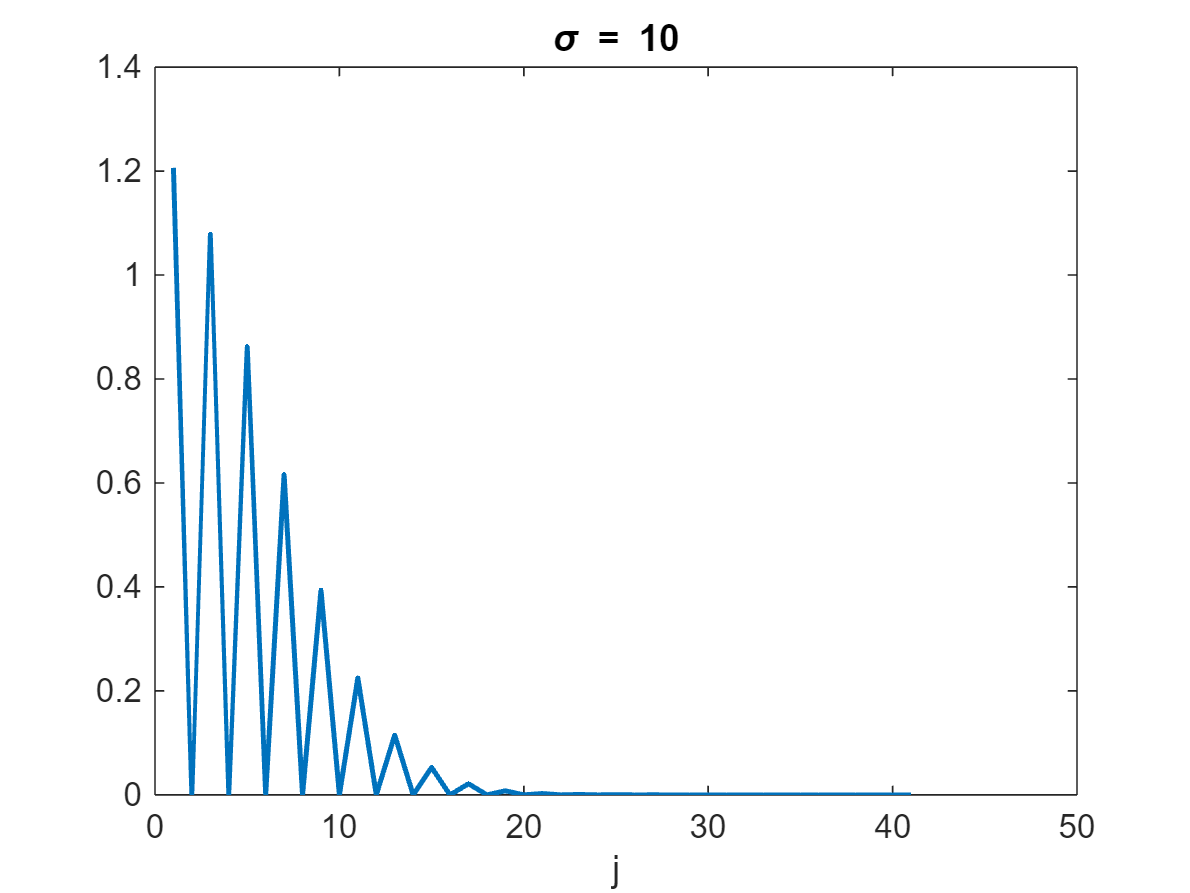

figure(10);
plot(abs(c1),'LineWidth',1.5);
title('\sigma = 10');
xlabel('j');

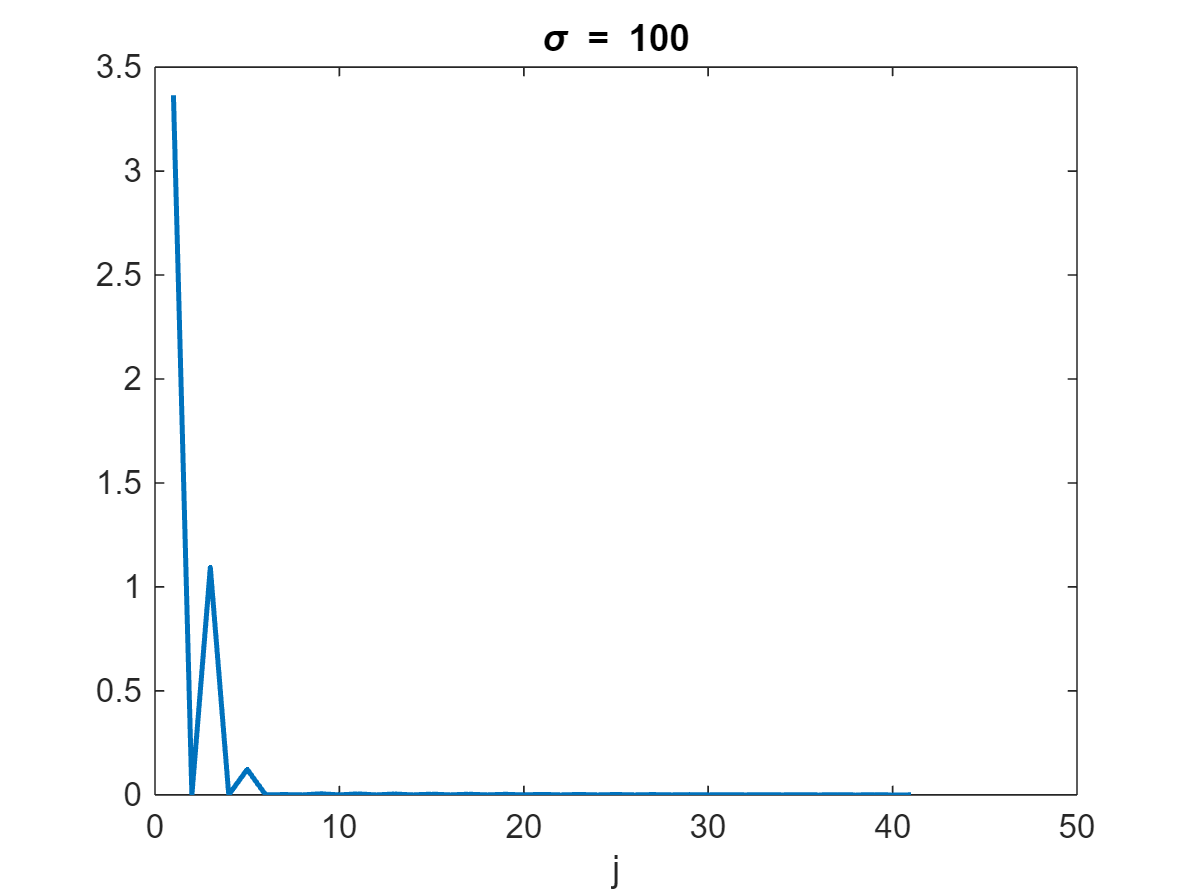

figure(11);
plot(abs(c2),'LineWidth',1.5);
title('\sigma = 100');
xlabel('j');

f.) This will have something to do with the fact that I could approximate $x_\mu$for $\sigma = 100$ has a sum of the first few terms